%Kaleb Nails
%}Jose Rocha
% For Graphs in this the assumption is that the plane is working at max
% power. So as the plane goes faster the maximum thrust decreases

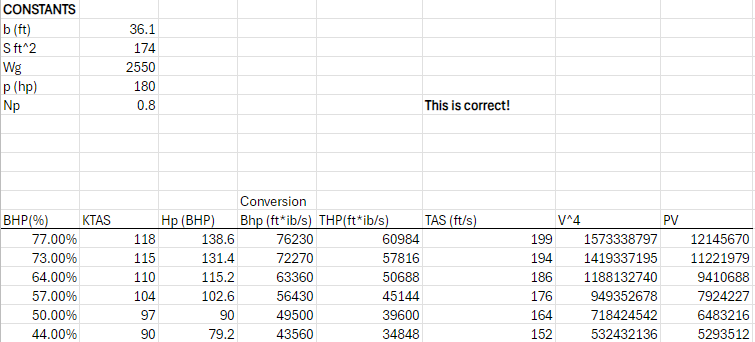

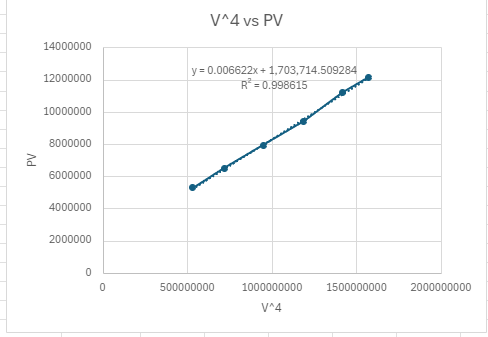

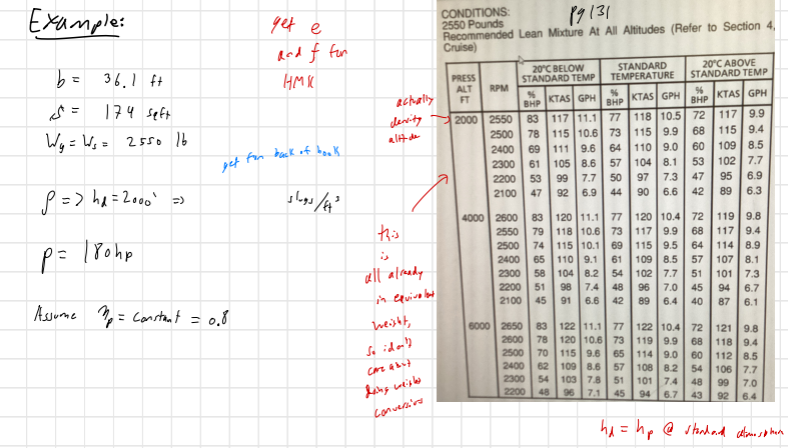

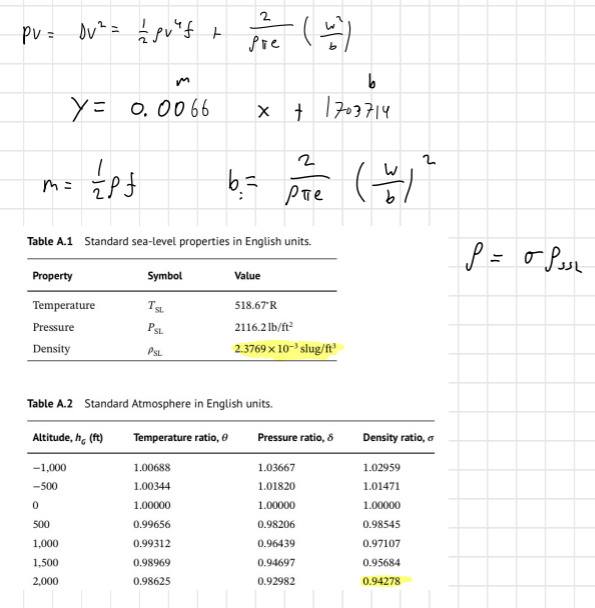

clc;clear;

%%%%%%%%%%%%%%%%%%
%CONSTANTS
w = 2550 %lb

w = 2550

b = 36.1 %ft

b = 36.1000


%%%%%%%%%%%%%%%%%%%%%%%
%Determine f and e at standard temp
m = 0.006622; %These values come from excel
b_intercept=1703714;

ro_SSL = 2.24*10^-3;
omega = 0.94278;
ro = ro_SSL*omega

ro = 0.0021


f = 2*m/ro

f = 6.2713


syms e
eqn = b_intercept == 2/(ro*pi*e)*(w/b)^2;
e = solve(eqn);

fprintf("The oswald efficiency factor (e) is %.3f \nThe equivalent flat plate area (f) is %.3f sq-ft\n", e, f);

The oswald efficiency factor (e) is 0.883 
The equivalent flat plate area (f) is 6.271 sq-ft


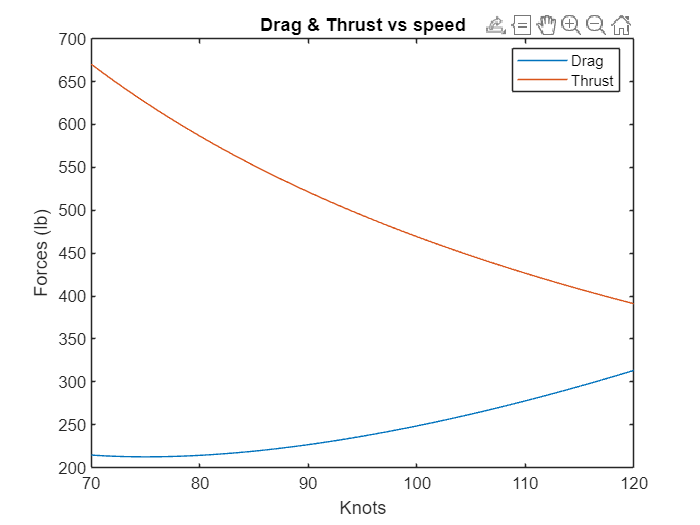


%%%%%%%%%%%%%%%%%%%
%Plot drag
knot_range = 70:1:120;
v = knot_range*1.68781;

D = .5*ro*v.^2*f + 2/(ro*pi()*e)*(w/b)^2*1./v.^2;

plot(knot_range,D)
title('Drag & Thrust vs speed'); xlabel('Knots');ylabel('Forces (lb)')
hold on;

%use the table BHP% to get THP from the excel
THP = [60984, 57816, 50688, 45144, 39600, 34848]; %this is the same as excess power
THP_knots = [118,115,110,104,97,90];
P_a= 180*.8*550; %This assumes full tilt throttle

%Convert to correct units so you can use P=TV and divide the power by V
THP_thrust = P_a./v; %lb, divide the power by the velocity to get thrust
plot(knot_range,THP_thrust)
legend('Drag','Thrust','Location','best')
hold off

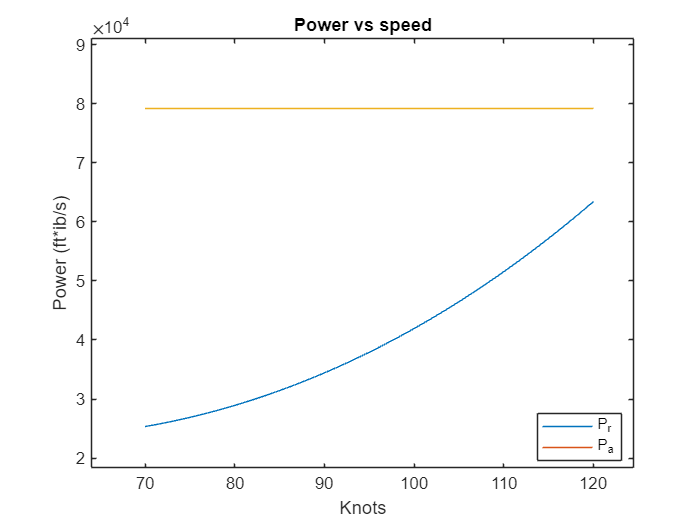


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%4. Plot power required and power available versus speed on a new figure.
P_r = .5*ro*v.^3*f + 2/(ro*pi()*e)*(w/b)^2*1./v;
plot(knot_range,P_r)
hold on
plot(knot_range,P_a*ones(length(knot_range)))
title('Power vs speed'); xlabel('Knots');ylabel('Power (ft*ib/s)');
legend('P_r','P_a','Location','best');
hold off

xlim([64.0 124.5])
ylim([18404 91004])

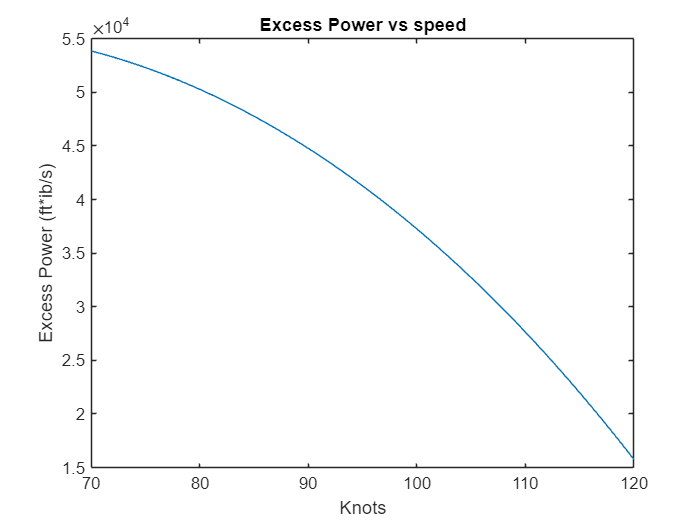


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%5. Plot excess power versus speed on a new figure.

P_e = P_a-P_r;
plot(knot_range,P_e)
title('Excess Power vs speed'); xlabel('Knots');ylabel('Excess Power (ft*ib/s)')

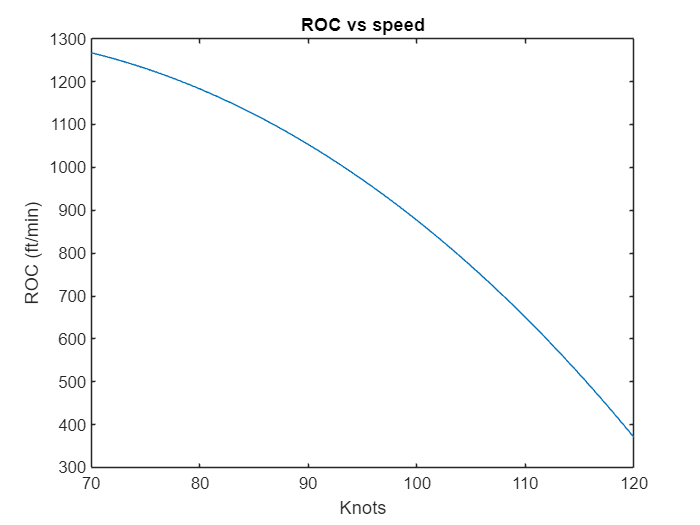


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%6. Plot rate of climb in ft/min versus speed on a new figure.
ROC = P_e./w*60;
plot(knot_range,ROC)
title('ROC vs speed'); xlabel('Knots');ylabel('ROC (ft/min)')

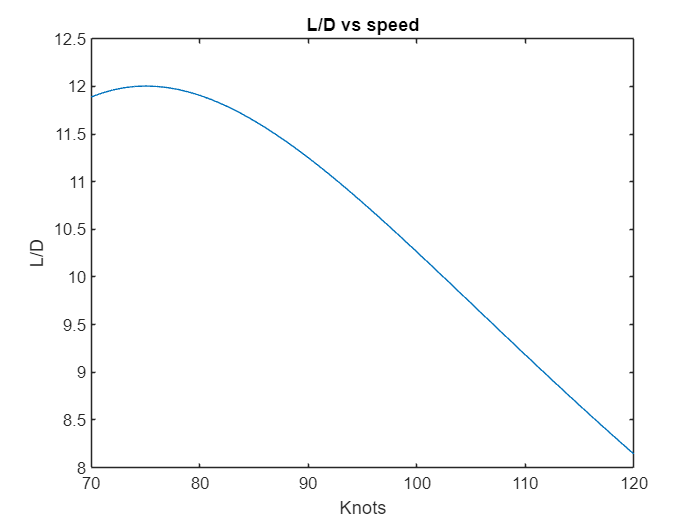


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%7. Plot L/D versus speed on a new figure.     
plot(knot_range,w./D)
title('L/D vs speed'); xlabel('Knots');ylabel('L/D')